# Run this after Tester.mlx

model_name = "sin0d1"

model_name = "sin0d1"


load("model_predict\predict_sin0d1.mat");
%model_predict_signals = data.Data
model_predict_signals = {data.Data(:, 1), 
                        data.Data(:, 2),
                        data.Data(:, 3),
                        data.Data(:, 4),
                        data.Data(:, 5)}

model_predict_signals = 5×1 cell array
    {10001×1 double}
    {10001×1 double}
    {10001×1 double}
    {10001×1 double}
    {10001×1 double}


## Plot input test, measure, predict and Compare

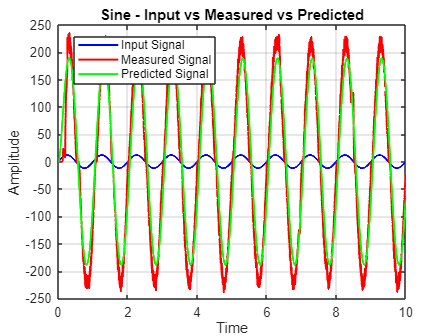

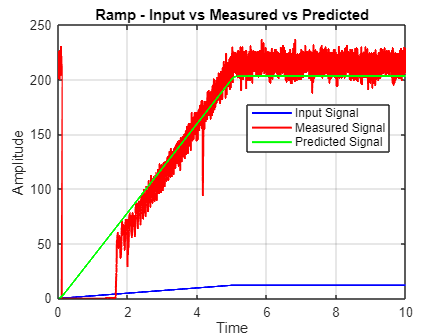

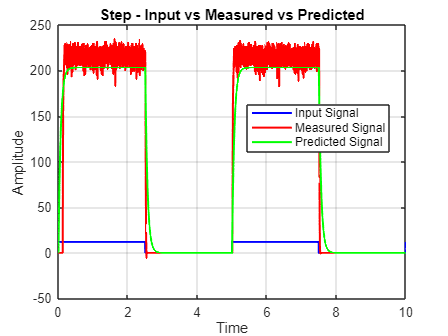

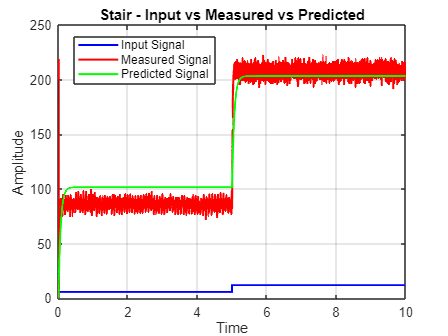

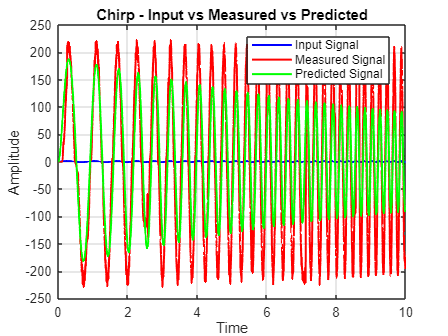


% Define colors for better visibility
colors = {'b', 'r', 'g'}; % Blue for input, Red for measured, Green for model prediction

% Loop through each test signal and plot with model predictions
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Comparison']);
    
    % Plot Input Test Signal
    plot(TimeArr, Inp_test_signals{i}, 'Color', colors{1}, 'LineWidth', 1.5);
    hold on;
    
    % Plot Measured Signal
    plot(TimeArr, Measure_test_signals{i}, 'Color', colors{2}, 'LineWidth', 1.5);
    
    % Plot Model Predicted Signal
    plot(TimeArr, model_predict_signals{i}, 'Color', colors{3}, 'LineWidth', 1.5);
    
    % Add Title and Legend
    title([Test_signal_names{i}, ' - Input vs Measured vs Predicted']);
    legend('Input Signal', 'Measured Signal', 'Predicted Signal', 'Location', 'best');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
    hold off;
end

% Function to compute R-squared
function R_squared = compute_rsquare(y_actual, y_pred)
    % Ensure input vectors are column vectors
    y_actual = y_actual(:);
    y_pred = y_pred(:);
    
    % Compute SSE (Sum of Squared Errors)
    SSE = sum((y_actual - y_pred).^2);
    
    % Compute SStot (Total Sum of Squares)
    SS_tot = sum((y_actual - mean(y_actual)).^2);
    
    % Compute R-squared
    R_squared = 1 - (SSE / SS_tot);
end

compute_rsquare(Measure_test_signals{1}, model_predict_signals{1})

ans = single
0.9373


% Compute R-squared for each signal type
R_squared_values = zeros(1, length(Test_signal_names));

fprintf('R-squared values for each test signal:\n');

R-squared values for each test signal:


for i = 1:length(Test_signal_names)
    R_squared_values(i) = compute_rsquare(Measure_test_signals{i}, model_predict_signals{i});
    fprintf('%s: %.4f\n', Test_signal_names{i}, R_squared_values(i));
end

Sine: 0.9373
Ramp: 0.8799
Step: 0.9570
Stair: 0.9436
Chirp: 0.7517


% Define test signal names
%Test_signal_names = {'Sine', 'Ramp', 'Step', 'Stair', 'Chirp'};

% Get a list of all prediction files in the "model_predict" folder
prediction_files = dir('model_predict\predict_*.mat');

% Initialize a table to store R-squared values
num_models = length(prediction_files);
num_signals = length(Test_signal_names);
R_squared_table = zeros(num_models, num_signals);
model_names = strings(num_models, 1);

% Loop through each predicted signal file
for file_idx = 1:num_models
    % Extract the file name and load the data
    file_name = prediction_files(file_idx).name;
    model_name = erase(file_name, {'predict_', '.mat'}); % Remove prefixes
    model_names(file_idx) = model_name; % Store model name
    
    % Load the predicted data
    load(fullfile('model_predict', file_name));
    
    % Extract model predictions (assuming 5 columns in the .mat file)
    model_predict_signals = {data.Data(:, 1), data.Data(:, 2), data.Data(:, 3), data.Data(:, 4), data.Data(:, 5)};
    
    % Compute R-squared for each test signal
    for i = 1:num_signals
        R_squared_table(file_idx, i) = compute_rsquare(Measure_test_signals{i}, model_predict_signals{i});
    end
end

R_squared_table

R_squared_table =     0.8964    0.6724    0.8614    0.7081    0.7321
    0.9459    0.8835    0.9607    0.9366    0.7757
    0.9088    0.7201    0.8831    0.7722    0.7475
    0.6467    0.8878    0.9071    0.9234    0.3747
    0.8672    0.8775    0.9449    0.9381    0.6036
    0.9285    0.8805    0.9561    0.9427    0.7269
    0.0183    0.2363   -0.1593    0.0492    0.0148
    0.0837    0.8088    0.3474    0.7189    0.0564
    0.1309    0.8617    0.5165    0.8005    0.0827
    0.9373    0.8799    0.9570    0.9436    0.7517


% Define test signal names
% Test_signal_names = {'Sine', 'Ramp', 'Step', 'Stair', 'Chirp'};

% Get a list of all prediction files in the "model_predict" folder
prediction_files = dir('model_predict\predict_*.mat');

% Initialize a table to store R-squared values
num_models = length(prediction_files);
num_signals = length(Test_signal_names);
R_squared_table = zeros(num_models, num_signals);
model_names = strings(num_models, 1);

% Loop through each predicted signal file
for file_idx = 1:num_models
    % Extract the file name and load the data
    file_name = prediction_files(file_idx).name;
    model_name = erase(file_name, {'predict_', '.mat'}); % Remove prefixes
    model_names(file_idx) = model_name; % Store model name
    
    % Load the predicted data
    load(fullfile('model_predict', file_name));
    
    % Extract model predictions (assuming 5 columns in the .mat file)
    model_predict_signals = {data.Data(:, 1), data.Data(:, 2), data.Data(:, 3), data.Data(:, 4), data.Data(:, 5)};
    
    % Loop through each test signal and plot with model predictions
    for i = 1:num_signals
        figure('Name', [Test_signal_names{i}, ' Comparison']);
        
        % Plot Input Test Signal
        plot(TimeArr, Inp_test_signals{i}, 'Color', 'b', 'LineWidth', 1.5);
        hold on;
        
        % Plot Measured Signal
        plot(TimeArr, Measure_test_signals{i}, 'Color', 'r', 'LineWidth', 1.5);
        
        % Plot Model Predicted Signal
        plot(TimeArr, model_predict_signals{i}, 'Color', 'g', 'LineWidth', 1.5);
        
        % Add Title and Legend
        title([Test_signal_names{i}, ' - ', model_name, ' - Input vs Measured vs Predicted']);
        legend('Input Signal', 'Measured Signal', 'Predicted Signal', 'Location', 'best');
        xlabel('Time');
        ylabel('Amplitude');
        grid on;
        hold off;
        
        % Save the graph in the "Validate_result" folder with the format "m_MODEL-t_TEST"
        save_path = fullfile('Validate_result', ['m_' model_name, '-t_', Test_signal_names{i}, '.png']);
        saveas(gcf, save_path);
    end
    
    % Compute R-squared for each test signal
    for i = 1:num_signals
        R_squared_table(file_idx, i) = compute_rsquare(Measure_test_signals{i}, model_predict_signals{i});
    end
end
